# Application Problems

## Problem 3.7 (Latent Semantic Indexing)

load("HW03\HW1_DataSet\wordVecV.mat")
M = V;
M( M < 1 ) = 0;
M( M > 0 ) = 1;
S = vecnorm(M);
Mnorm = V./S;

[U,S,V] = svd(Mnorm)

U =    -0.0023   -0.0106   -0.0019   -0.0201   -0.0031    0.0314    0.0015   -0.0186   -0.0114    0.0084    0.0006   -0.0248   -0.0248    0.0002   -0.0245    0.0003    0.0003    0.0003   -0.0005    0.0003    0.0003   -0.0495    0.0006   -0.0248   -0.0246    0.0004   -0.0002    0.0003    0.0002   -0.0248    0.0002    0.0002    0.0002   -0.0011   -0.0002    0.0001    0.0001    0.0003   -0.0005   -0.0003   -0.0492    0.0002   -0.0027    0.0006   -0.0005    0.0006    0.0008    0.0003   -0.0011   -0.0004
   -0.0047    0.0246   -0.0028   -0.0035    0.0119    0.0016    0.0091   -0.0077   -0.0055   -0.0005   -0.0298    0.0277    0.0277   -0.0006    0.0254    0.0004    0.0004    0.0004    0.0019    0.0004   -0.0023    0.0554   -0.0298    0.0277    0.0271   -0.0029    0.0026   -0.0023   -0.0006    0.0277   -0.0006   -0.0006   -0.0006   -0.0325    0.0026   -0.0279    0.0003   -0.0023    0.0019    0.0013    0.0559   -0.0006    0.0011   -0.0039    0.0019   -0.0298   -0.0069   -0.0023    0.0041    0

S =     8.8275         0         0         0         0         0         0         0         0         0
         0    2.4708         0         0         0         0         0         0         0         0
         0         0    2.0516         0         0         0         0         0         0         0
         0         0         0    1.9314         0         0         0         0         0         0
         0         0         0         0    1.7457         0         0         0         0         0
         0         0         0         0         0    1.6522         0         0         0         0
         0         0         0         0         0         0    1.5659         0         0         0
         0         0         0         0         0         0         0    1.4216         0         0
         0         0         0         0         0         0         0         0    1.3984         0
         0         0         0         0         0         0         0         0       

V =    -0.2384    0.0341   -0.0363    0.0792   -0.3099    0.1779   -0.0335    0.7719   -0.4308    0.1555
   -0.2943    0.0604   -0.2810    0.1806   -0.3412   -0.0649   -0.7848   -0.2367    0.0684   -0.0320
   -0.3180   -0.2908   -0.6076   -0.3131   -0.0798   -0.4527    0.2980    0.1123    0.1820   -0.0365
   -0.3067    0.4894   -0.4545    0.3962    0.3190    0.3047    0.2805   -0.1483   -0.0447    0.0745
   -0.2536   -0.3277   -0.0498   -0.4841   -0.0672    0.6483    0.0286   -0.3297   -0.1998    0.1315
   -0.4357    0.5884    0.3470   -0.5081    0.0535   -0.2535   -0.0251   -0.0468   -0.0909   -0.0852
   -0.2380    0.0588    0.2250    0.0935   -0.3794    0.3095    0.1982    0.1532    0.7506   -0.1210
   -0.2034   -0.0907    0.2573    0.3079   -0.4041   -0.2829    0.3213   -0.3700   -0.1858    0.5210
   -0.4261   -0.3430    0.2496    0.1325    0.6033   -0.0643   -0.2315    0.1772    0.2132    0.3499
   -0.3574   -0.2970    0.2047    0.3043    0.0307   -0.0431    0.1343   -0.1042   -0.2

### Part A)

If since matrix M is the term-by-document matrix and we know that U and V are produced from MM' (document-to-document) and M'M (term-to-term) matricies we can imagine the vectors of U to represent how close the documents are together and V to represent how close the terms are together. 

### Part B)

k= 3;
U_k = U(:, 1:k)

U_k =    -0.0023   -0.0106   -0.0019
   -0.0047    0.0246   -0.0028
   -0.0017    0.0009   -0.0011
   -0.0114   -0.0040   -0.0391
   -0.0113   -0.0141    0.0042
   -0.0023   -0.0106   -0.0019
   -0.0023   -0.0106   -0.0019
   -0.0029   -0.0084    0.0074
   -0.0017    0.0009   -0.0011
   -0.0045    0.0033   -0.0186


% S_k = S(1:k, 1:k);
% V_k = V(:, 1:k);
% Mnorm_k = U_k * S_k * V_k';

### Part C)

largest_elements = maxk(S(:), 10)

largest_elements =     8.8275
    2.4708
    2.0516
    1.9314
    1.7457
    1.6522
    1.5659
    1.4216
    1.3984
    1.2598


### Part d)

k= 9;
U_k = U(:, 1:k);
S_k = S(1:k, 1:k);
V_k = V(:, 1:k);
Mnorm_k = U_k * S_k * V_k';
[angles,i]=pdist2(Mnorm_k',Mnorm_k',"cosine","Smallest",2);
[min_angle,index] = mink(angles(2,:),1);
pair = i(2,index);
display([min_angle,index,pair])

    0.0717    9.0000   10.0000



09: Barack Obama

10: George W. Bush

### Part e)

for k= 1:8
    U_k = U(:, 1:k);
    S_k = S(1:k, 1:k);
    V_k = V(:, 1:k);
    Mnorm_k = U_k * S_k * V_k';
    [angles,i]=pdist2(Mnorm_k',Mnorm_k',"cosine","Smallest",2);
    [min_angle,index] = mink(angles(2,:),1);
    pair = i(2,index);
    display([k,min_angle,index,pair])
end

     1     0     1     2

    2.0000    0.0000    9.0000   10.0000

    3.0000    0.0000    9.0000   10.0000

    4.0000    0.0063    9.0000   10.0000

    5.0000    0.0178    1.0000    2.0000

    6.0000    0.0325    1.0000    2.0000

    7.0000    0.0453    1.0000    7.0000

    8.0000    0.0536    9.0000   10.0000



The lowest value of k that still gives the same answer is 2. 

The pair of similar documents for k-1 is:

01: B. J. Cole

02: Mary J. Blige

## Problem 3.8 (Eigenfaces and l2 projection)

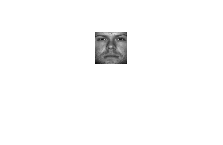

load("HW03\HW3_DataSet\yalefaces.mat")
figure;
imshow(M(:,:,1)/255)

N = number of images = 2414

d = number of pixels in image = 1024 = 32*32

x^(i) = a flat vector of an image = 1xd = 1x1024

x bar = average of all x^(i)s = average face

x^(i) bar = x^(i) - x bar = centered data

Mflat = reshape(M,1024,[])

Mflat =     82    86    76    15    70    53   101    94   118    90   117   120   104    72    99   161   157    54   118   140    88   186   131   212   164   114   215   156   207   234   162    20   131   201   172    70    72    62    49    65    46    47    19    31    14    10    14     8     5     5
    81    86    88    16    69    51   101    93   120    93   117   121   105    70   101   157   154    50   117   140    91   182   136   211   175   116   212   160   210   245   166    24   137   190   230    68    72    60    45    64    46    43    14    31    13    14    12     8     5     4
    72    74    80    22    48    37    79    69    90    84   104   110    97    59    93   136   134    57   102   119    72   156   114   178   167   106   197   148   198   244   173    40   131   225   253    54    53    45    30    51    31    29    10    20    11    17    13     6     6     5
    72    67    62    11    64    41    82    83    99    87    95   104    96    66    8

muX = sum(Mflat')' ./ 2414

muX =    62.3637
   62.4606
   57.5282
   53.5638
   49.6885
   52.2655
   59.1877
   63.2142
   67.4818
   73.6794


X = Mflat - muX

X =    19.6363   23.6363   13.6363  -47.3637    7.6363   -9.3637   38.6363   31.6363   55.6363   27.6363   54.6363   57.6363   41.6363    9.6363   36.6363   98.6363   94.6363   -8.3637   55.6363   77.6363   25.6363  123.6363   68.6363  149.6363  101.6363   51.6363  152.6363   93.6363  144.6363  171.6363   99.6363  -42.3637   68.6363  138.6363  109.6363    7.6363    9.6363   -0.3637  -13.3637    2.6363  -16.3637  -15.3637  -43.3637  -31.3637  -48.3637  -52.3637  -48.3637  -54.3637  -57.3637  -57.3637
   18.5394   23.5394   25.5394  -46.4606    6.5394  -11.4606   38.5394   30.5394   57.5394   30.5394   54.5394   58.5394   42.5394    7.5394   38.5394   94.5394   91.5394  -12.4606   54.5394   77.5394   28.5394  119.5394   73.5394  148.5394  112.5394   53.5394  149.5394   97.5394  147.5394  182.5394  103.5394  -38.4606   74.5394  127.5394  167.5394    5.5394    9.5394   -2.4606  -17.4606    1.5394  -16.4606  -19.4606  -48.4606  -31.4606  -49.4606  -48.4606  -50.4606  -54.4606  -57.4606  -58

C = X*X'

C = 	1.0e+07 *

    1.0834    1.0591    0.9640    0.8609    0.7183    0.6881    0.7272    0.7295    0.7635    0.8256    0.8814    0.8915    0.9174    0.9426    0.9408    0.9116    0.9124    0.9119    0.9169    0.8982    0.9039    0.8907    0.8881    0.8775    0.8429    0.8066    0.8121    0.7850    0.7289    0.7491    0.7363    0.7235    1.0495    0.9929    0.8586    0.7010    0.5582    0.5978    0.5805    0.5507    0.5936    0.7658    0.8452    0.8363    0.8293    0.8491    0.8328    0.8431    0.8475    0.8518
    1.0591    1.0845    0.9946    0.8738    0.7132    0.6738    0.7165    0.7171    0.7496    0.8158    0.8785    0.8920    0.9205    0.9420    0.9362    0.9051    0.9059    0.9066    0.9101    0.8890    0.8965    0.8835    0.8806    0.8711    0.8354    0.7991    0.7943    0.7593    0.7013    0.7268    0.7175    0.7046    1.0467    1.0167    0.8696    0.6862    0.5396    0.5829    0.5722    0.5347    0.5713    0.7594    0.8412    0.8355    0.8280    0.8463    0.8270    0.8317   

### Part a)

Looking at `X = UΣV' and C = X' * X we can see that`

The eigenvalues of C are the squares of the singular values of X. This means that if σ is a singular value of X, then σ^2 is an eigenvalue of C.

Additionally, the left-singular vectors of X (the columns of U) are the same as the eigenvectors of C.

### Part b)

[V, D] = eig(C);
eigenvalues = flip(diag(D))

eigenvalues = 	1.0e+09 *

    3.3037
    3.2362
    0.4473
    0.2597
    0.1409
    0.1297
    0.0966
    0.0858
    0.0667
    0.0615


eigenvectors = flip(V')'

eigenvectors =     0.0130    0.0432    0.0129   -0.0753   -0.0396   -0.0243   -0.0796   -0.0188   -0.0186   -0.0532    0.0184   -0.0170    0.0062   -0.0484   -0.0355    0.0016    0.0447   -0.0276   -0.0194   -0.0437   -0.0455    0.0130   -0.0050   -0.0364    0.0060   -0.0351    0.0001    0.0074   -0.0623    0.0140   -0.0650    0.0626    0.0505   -0.0327    0.0632   -0.0168   -0.0100    0.0344    0.0341   -0.0488   -0.0104    0.0017    0.0122   -0.0404   -0.0095    0.0179   -0.0102    0.0276    0.0441    0.0061
    0.0118    0.0434    0.0098   -0.0746   -0.0409   -0.0270   -0.0892   -0.0162   -0.0076   -0.0465    0.0213   -0.0134    0.0182   -0.0405   -0.0281   -0.0022    0.0437   -0.0213   -0.0338   -0.0202   -0.0378    0.0080    0.0143   -0.0392    0.0137   -0.0438    0.0084    0.0184   -0.0669    0.0138   -0.0953    0.0672    0.0477   -0.0263    0.0417   -0.0216    0.0017    0.0427    0.0309   -0.0540    0.0036    0.0095    0.0156   -0.0580   -0.0063    0.0197   -0.0197    0.0225    

The eigen values are all real. 

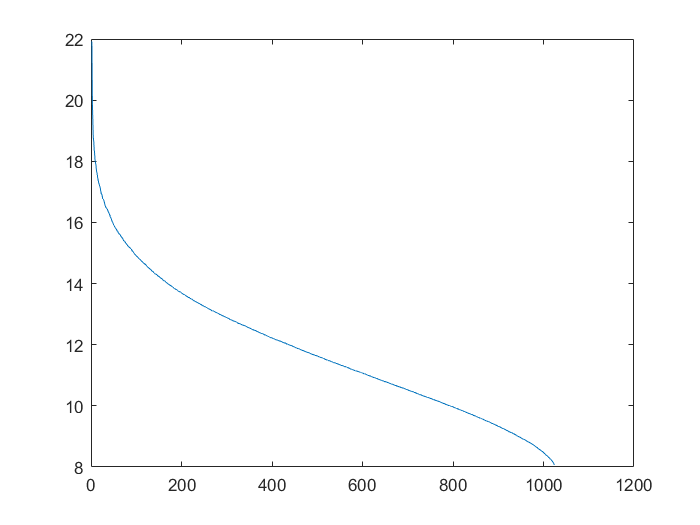

plot(log(eigenvalues))

### Part c)

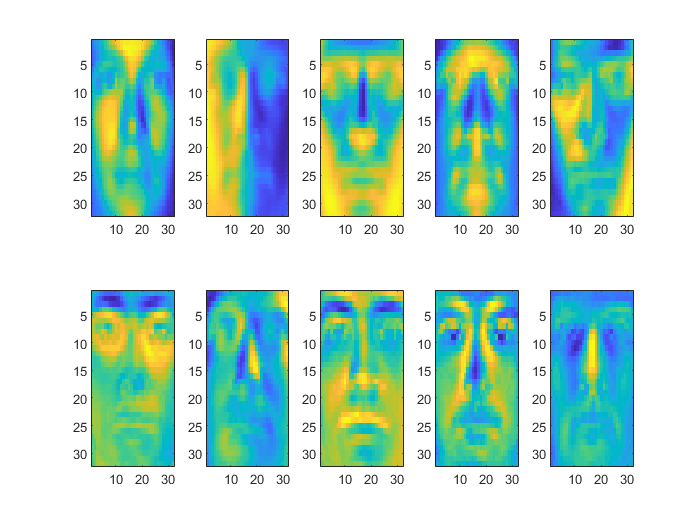

L = reshape(eigenvectors, 32,32,[]);
figure;
tiledlayout(2,5)
for i = 1:10
    nexttile;
    imagesc(L(:,:,i))
end

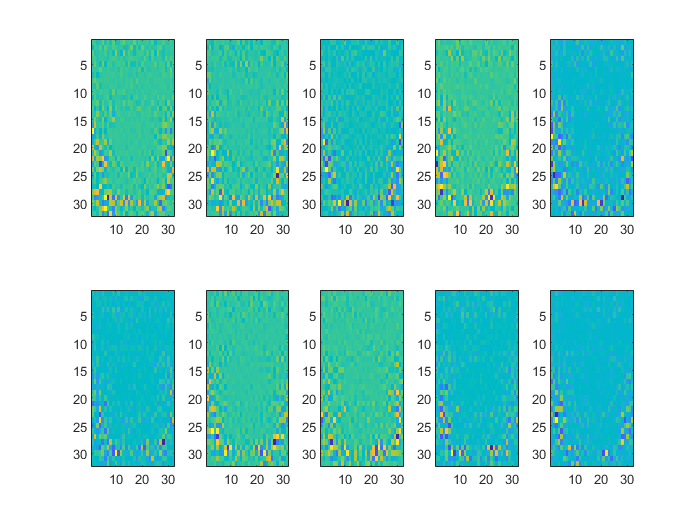

figure;
tiledlayout(2,5)
for i = 1024-9:1024
    nexttile;
    imagesc(L(:,:,i))
end